x = [6 8];
norm(x)

ans =       10       


벡터 크기 계산

x1 = x/norm(x)

x1 =        3/5            4/5     


벡터 정규화(벡터를 크기로 나눔)

u = [2 6 5]

u =        2              6              5       


v = [-4 3 -2]

v =       -4              3             -2       


dot(u,v)

ans =        0       


theta = acos(dot(u,v)/norm(u)/norm(v))

theta =      355/226   


degree = theta/pi*180

degree =       90       


벡터의 내적

cross(u,v)

ans =      -27            -16             30       


벡터의 외적

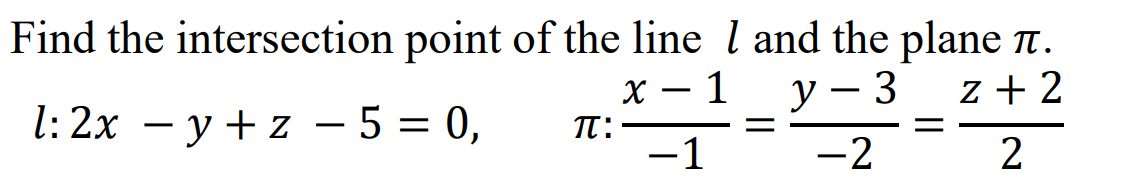

syms x y z % symbolic 변수로 처리
t = sym('t')

$$t = t$$

x = -t+1; y = -2*t+3; z = 2*t-2;
solve(2*x-y+z-5==0, t)

$$ans = 4$$

u1 = [-5 1 2]; u2 = [3 -7 1]; u3 = [-2 -6 3];
A = [u1;u2;u3]

A =       -5              1              2       
       3             -7              1       
      -2             -6              3       


rank(A) % rank < 3 -> 일차종속

ans =        2       


det(A)

ans =        0       


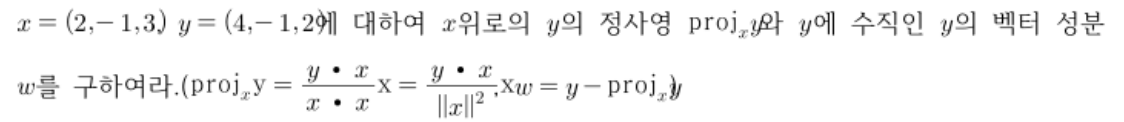

x = [2 -1 3]; y = [4 -1 2]

y =        4             -1              2       


proj = dot(y,x)/dot(x,x)*x

proj =       15/7          -15/14          45/14    


w = y-proj

w =       13/7            1/14         -17/14    


u = dot([3,-1,2],[1,3,-2])-6

u =      -10       


v = norm([1,3,-2])

v =     3476/929   


d = abs(u)/v

d =     2547/953   


A = [1 1 2; 2 4 -3; 3 6 -5]

A =        1              1              2       
       2              4             -3       
       3              6             -5       


X = [9; 1; 0]

X =        9       
       1       
       0       


AX = [A,X] % 붙임행렬 생성

AX =        1              1              2              9       
       2              4             -3              1       
       3              6             -5              0       


%rref(AX)

Matrix Multiplication

A = [1 2 -1; 3 1 0]; B = [-2 1; 0 -3; 2 1];
A * B

ans =       -4             -6       
      -6              0       


A = [1 2;-1 3; 1 0]

A =        1              2       
      -1              3       
       1              0       


A.*B %.을 붙이면 성분 별 연산

ans =       -2              2       
       0             -9       
       2              0       


A./B % 성분끼리 나눗셈

ans =       -1/2            2       
      -1/0           -1       
       1/2            0       


A.^B % 성분끼리 제곱

ans =        1              2       
       1              1/27    
       1              0       


C = inv([1 4 3;2 5 6;0 0 0])

C =        1/0            1/0            1/0     
       1/0            1/0            1/0     
       1/0            1/0            1/0     


if inv(C) ~= Inf
    disp('no inverse')
end

no inverse


backslash operator

A = [1 2 3;2 5 3;1 0 8]; b = [1; 3; -1];
A\b

ans =       -1       
       1       
       0       


inv(A)*b

ans =       -1       
       1       
      -1/1501199875790165


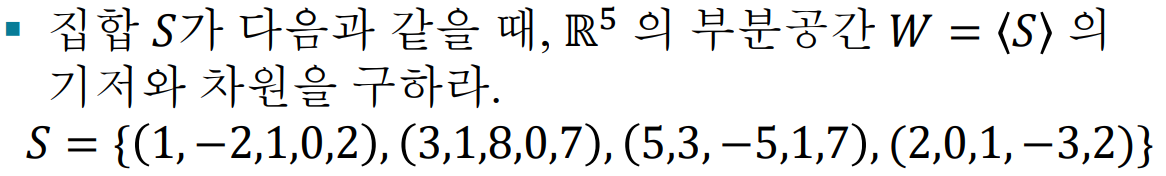

format rat
A = [1 -2 1 0 2;3 1 8 0 7;5 3 -5 1 7;2 0 1 -3 2];
% rref(A)

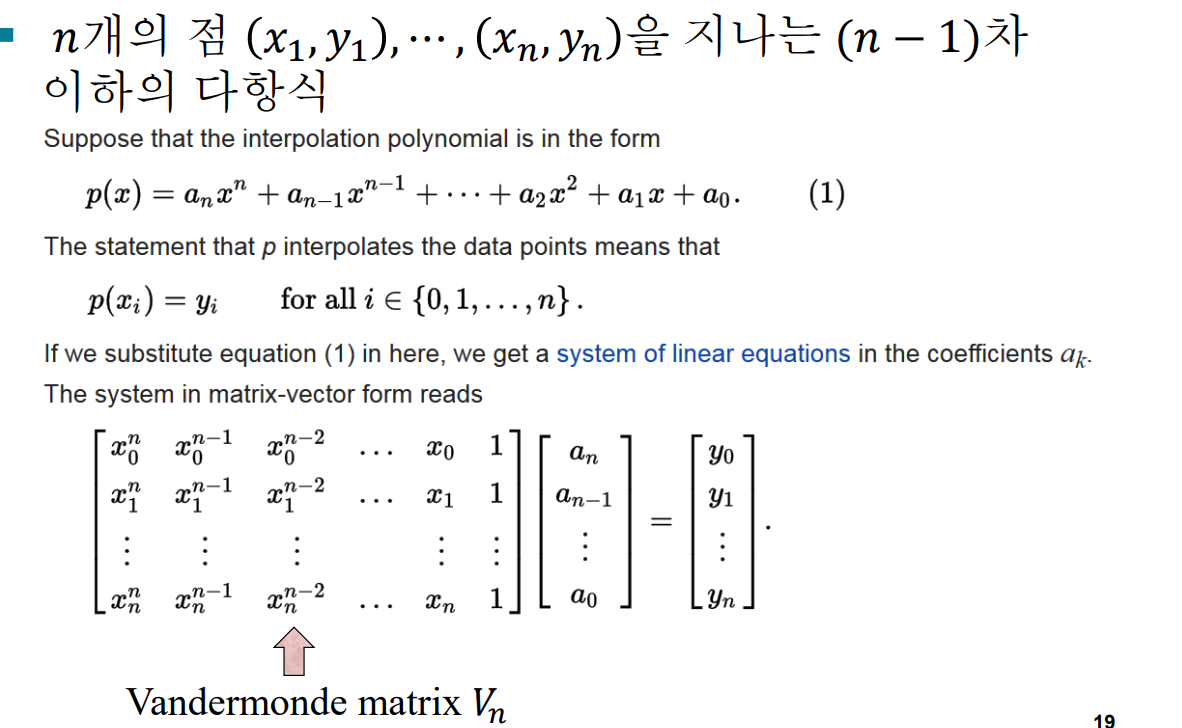

X = [-1 0 1 3];
A = vander(X)

A =       -1              1             -1              1       
       0              0              0              1       
       1              1              1              1       
      27              9              3              1       


B = [3 4 2 6]';
C = inv(A)*B

C =       17/24    
      -3/2     
     -29/24    
       4       


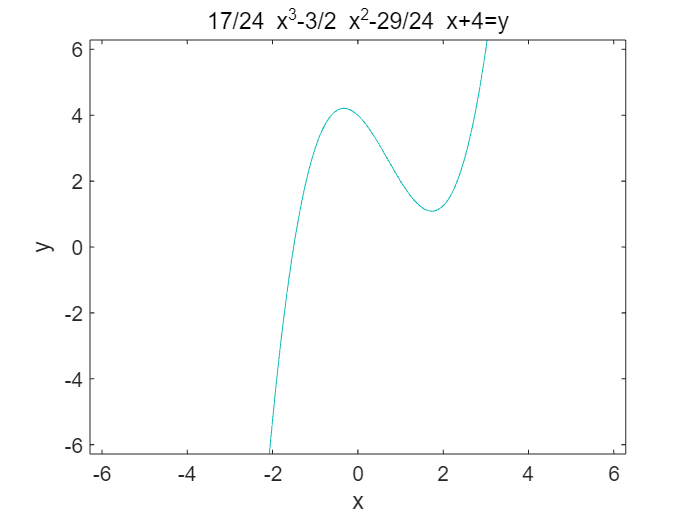

ezplot('17/24*x^3-3/2*x^2-29/24*x+4=y')

LU decomposition

A = [1 2 3;4 5 6;7 8 9];
[L1, U1] = lu(A)

L1 =        1/7            1              0       
       4/7            1/2            1       
       1              0              0       


U1 =        7              8              9       
       0              6/7           12/7     
       0              0              *       
